# **Gol'dberg representation**

**2023-03-27**

**Vibration and Acoustic Transducers Laboratory**

**Pohang University of Science and Technology**

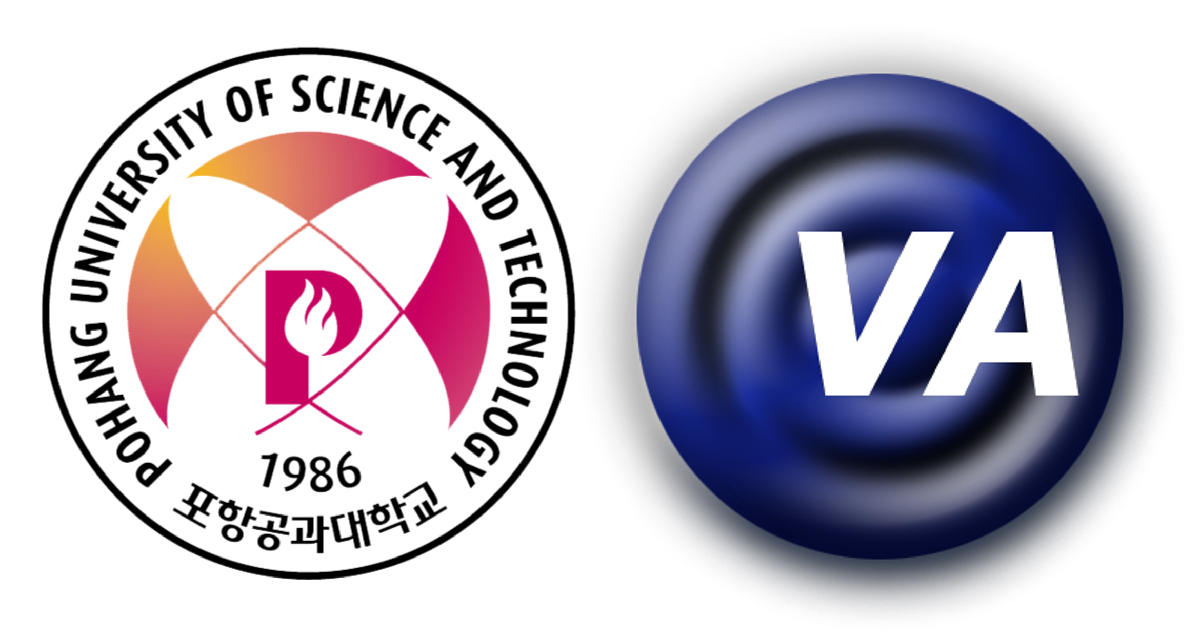

***Woongji Kim***

[wj.kim@postech.ac.kr](mailto:wj.kim@postech.ac.kr)

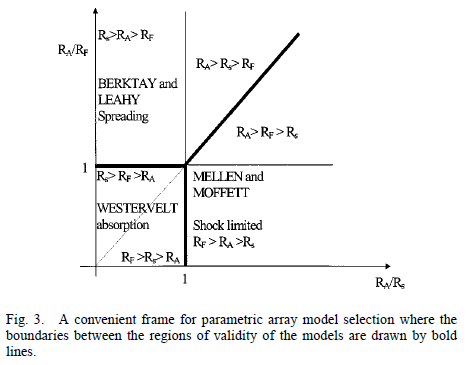

## Reference

- Kopp, L., et al. (2000). "Potential performance of parametric communications." IEEE Journal of Oceanic Engineering 25(3): 282-295.

###     Absorption limited model

- Westervelt, P. J. (1963). "Parametric Acoustic Array." The Journal of the Acoustical Society of America 35(4): 535-537.

###     Spreading limited Model

- Berktay, H. O. and D. J. Leahy (1974). "Farfield performance of parametric transmitters." The Journal of the Acoustical Society of America 55(3): 539-546.

###     Shock-wave limtied model

- Moffett, M. B. and R. H. Mellen (1977). "Model for parametric acoustic sources." The Journal of the Acoustical Society of America 61(2): 325-337.

## 3 basic distances which control the behavior of the parametric array

- Absorption length:                 $R_{A}=L_{a}=\frac{1}{\alpha\left(f_{p}\right)}$

- Rayleigh distnace:                 $R_{F}=z_{0}
=\frac{1}{2}ka^{2}
=\frac{\pi a^{2}}{\lambda_{p}}
=\frac{\pi a^{2}f_p}{c_{0}}$

- Shock formation distance:    $R_{S}=\bar{x}
=\frac{1}{\beta \varepsilon k_{p}}
=\frac{c_0}{2\pi \beta \varepsilon f_p}
=\frac{c_0^{2}}{2\pi \beta u_p f_p}$

## 3 basic modeling options

- Absorption limited

- Westervelt's initial model

- Design parameter:    $f_{p}$

- Spreading limited

- Berktay and Leahy

- Design parameter:    $f_{p}$, $a$

- Shock-wave limtied

- Mellen and Moffett

- Design parameter:    $f_{p}$, $a$, $u_{p}$

## Gol'dberg representation

- Gol'dberg number:                                                    $X=\Gamma=\frac{R_A}{R_S}=\frac{\beta \varepsilon k_{p}}{\alpha_p}
=\frac{2\pi \beta u_p f_p}{c_0^{2} \alpha \left(f_p \right)}$

- A properly normalized inverse Rayleigh distance:    $Y=\frac{R_A}{R_F}=\frac{\lambda_p}{\alpha_p \pi a^2}

=\frac{c_{0}}{\pi a^{2}f_p \alpha \left( f_p \right)}$

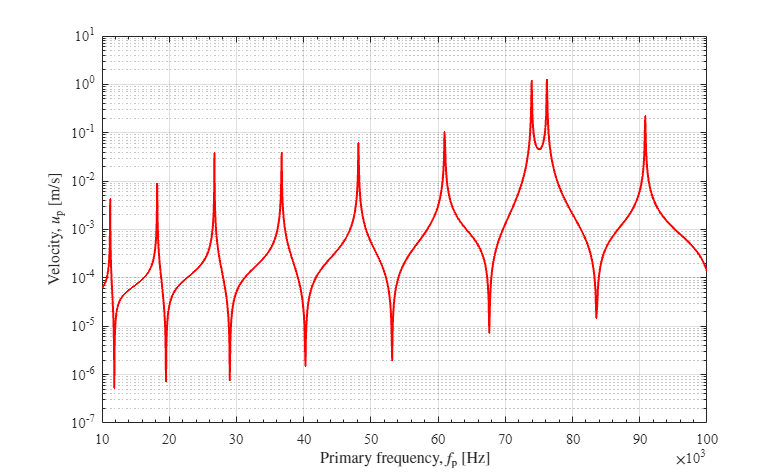

clear

air = importfile_air('air.txt');

% a0 = 10e-3:10e-3:50e-3;
a0 = 50e-3;

fr_comsol = importfile_COMSOL_fr('230406 -Langevin, stepped-horn and plate.txt');
freq_p = fr_comsol.freq(1:end)';
u_pt = fr_comsol.v(1:end)'/10;

u_pn = 5;
u_p = logspace(-2,0,u_pn);
u_p = u_p'*ones(length(freq_p),1)';

alpha = air_absorption(freq_p,20,20,1);

createfigure_xy_multi(freq_p,u_pt, ...
    'Primary frequency, $f_\mathrm{p}$ [Hz]','Velocity, $u_\mathrm{p}$ [m/s]', ...
    'linear','log','centimeters',18,9);

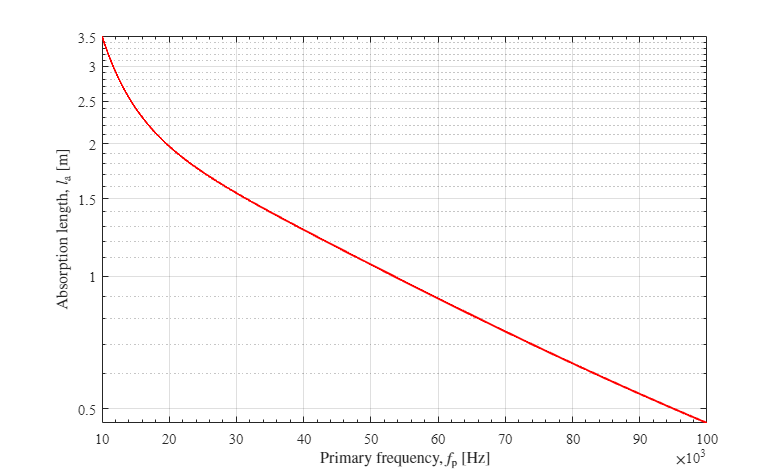


% Absorption length
l_alpha = 1./alpha;
createfigure_xy_multi(freq_p,l_alpha, ...
    'Primary frequency, $f_\mathrm{p}$ [Hz]','Absorption length, $l_\mathrm{a}$ [m]', ...
    'linear','log','centimeters',18,9);

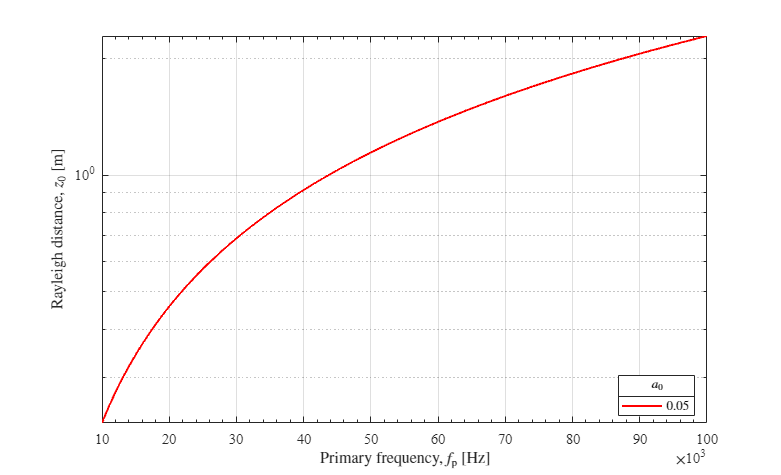


% Rayleigh distance
z0 = pi*a0'.^2*freq_p/air.c0;
createfigure_xy_multi(freq_p,z0, ...
    'Primary frequency, $f_\mathrm{p}$ [Hz]','Rayleigh distance, $z_0$ [m]', ...
    'linear','log','centimeters',18,9,'$a_0$',string(a0))

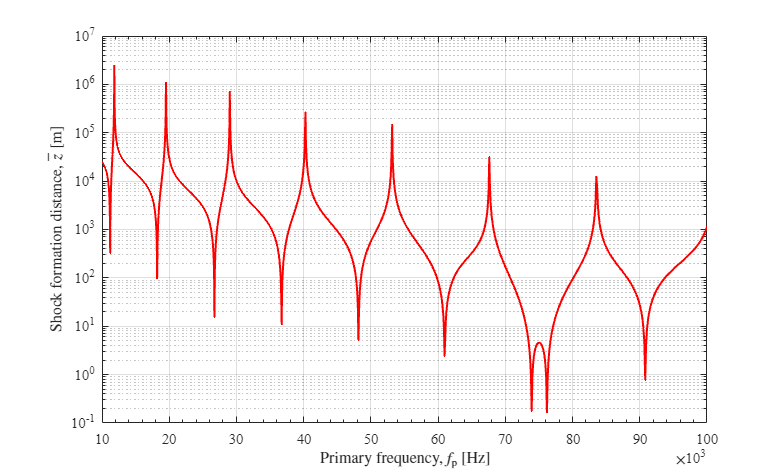


% Shock formation distance
z_t = air.c0^2./(2*pi*air.beta*u_pt.*freq_p);
z_ = air.c0^2./(2*pi*air.beta*u_p.*freq_p);
createfigure_xy_multi(freq_p,z_t, ...
    'Primary frequency, $f_\mathrm{p}$ [Hz]','Shock formation distance, $\bar{z}$ [m]', ...
    'linear','log','centimeters',18,9)

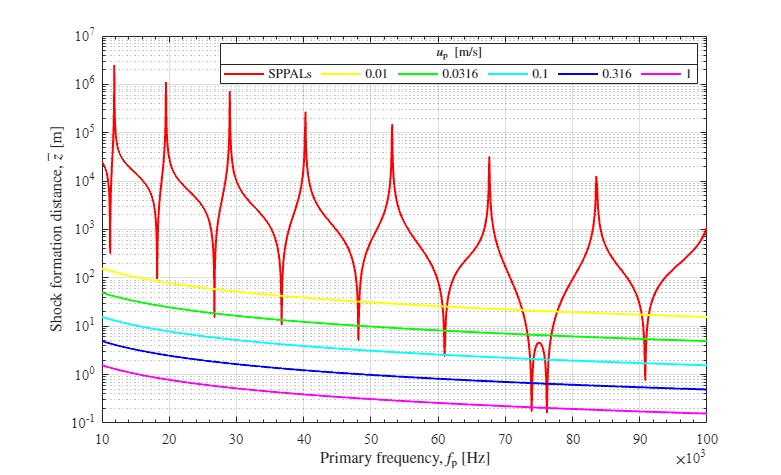

createfigure_xy_multi(freq_p,[z_t; z_], ...
    'Primary frequency, $f_\mathrm{p}$ [Hz]','Shock formation distance, $\bar{z}$ [m]', ...
    'linear','log','centimeters',18,9,'$u_\mathrm{p} \ \left[ \mathrm{m}/\mathrm{s} \right]$',['SPPALs'; compose("%.3g",u_p(:,1))])

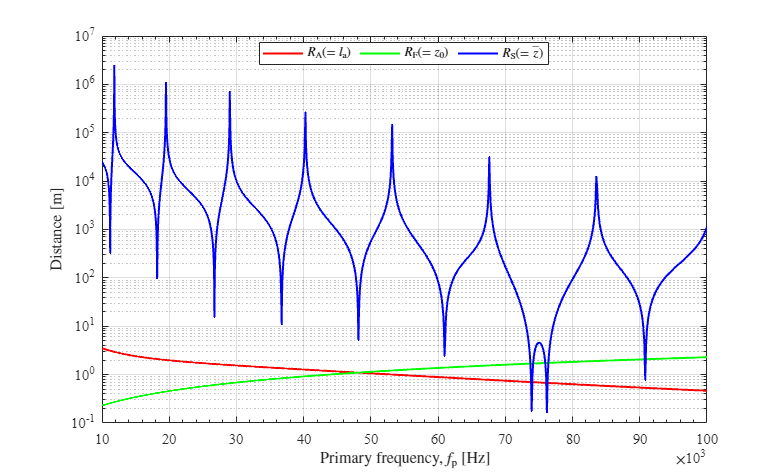


createfigure_xy_multi(freq_p,[l_alpha; z0; z_t], ...
    'Primary frequency, $f_\mathrm{p}$ [Hz]','Distance [m]', ...
    'linear','log','centimeters',18,9,'',["$R_\mathrm{A} \left(=l_\mathrm{a}\right)$" "$R_\mathrm{F} \left(=z_0\right)$" "$R_\mathrm{S} \left(=\bar{z}\right)$"])

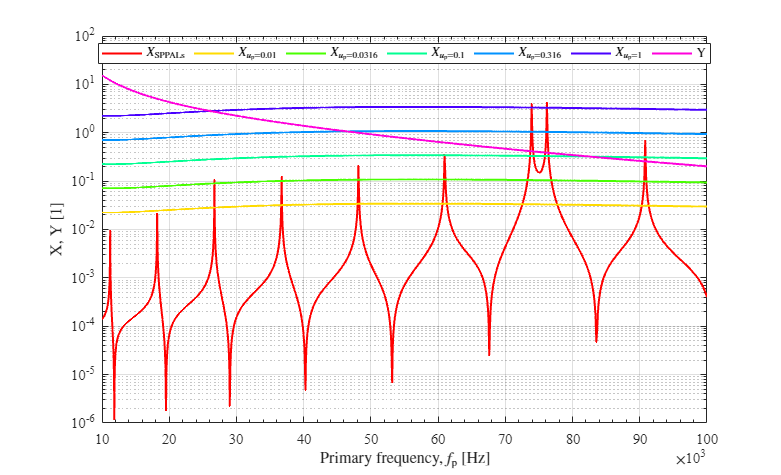


Xt = l_alpha./z_t;
X = repmat(l_alpha,u_pn,1)./z_;

Y = l_alpha./z0;

createfigure_xy_multi(freq_p,[Xt; X; Y], ...
    'Primary frequency, $f_\mathrm{p}$ [Hz]','X, Y [1]', ...
    'linear','log','centimeters',18,9,'',["$X_{\mathrm{SPPALs}}$" compose("$X_{u_\\mathrm{p}=%.3g}$",u_p(:,1)') "Y"])

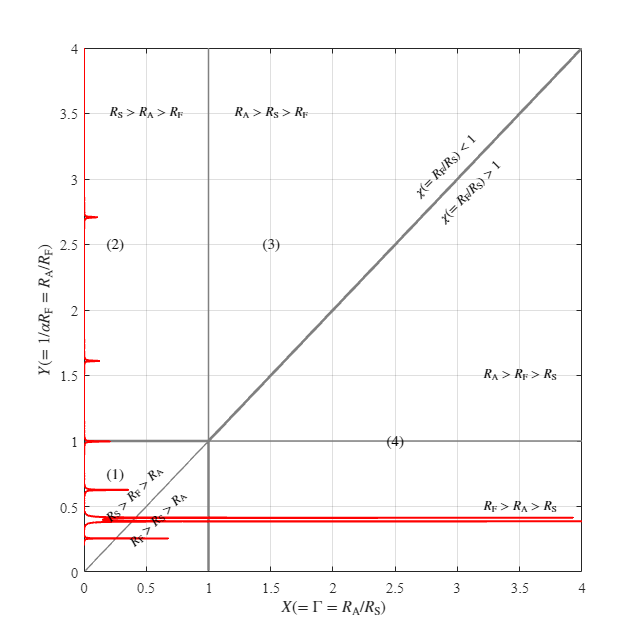


createfigure_goldberg(Xt, Y, 'linear')

- Small-signal absorption limiting in the collimated zone

- Absorption limiting in the far spherical zone

- Saturation limiting in the far spherical zone (but small-signal absorption limits the array length)

- Saturation limiting in the collimated zone

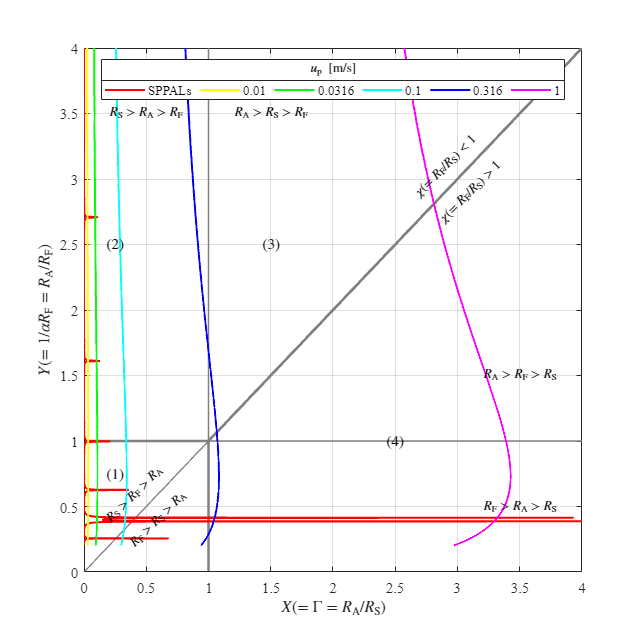

createfigure_goldberg([Xt; X], Y, 'linear', '$u_\mathrm{p} \ \left[ \mathrm{m}/\mathrm{s} \right]$',['SPPALs'; compose("%.3g",u_p(:,1))])

- Small-signal absorption limiting in the collimated zone

- Absorption limiting in the far spherical zone

- Saturation limiting in the far spherical zone (but small-signal absorption limits the array length)

- Saturation limiting in the collimated zone

## KZK equation


$$\frac{\partial^2p}{\partial z \partial \tau}
- \frac{c_0}{2} \nabla_\perp^2 p
- \frac{\delta}{2 c_0^3} \frac{\partial^3 p}{\partial \tau^3}
=
\frac{\beta}{2 \rho_0c_0^3} \frac{\partial^2 p^2}{\partial \tau^2}$$


###     Assumption regarding the source

- The source is defined in the plane, $z=0$.

- The source has a characteristic radius, $a$.

- The source radiates at frequencies that satisfy the relation, $ka \gg 1$.

The last assumption ensures that the beam is reaonably directional.

Because of the assumed directionality of the beam, the sound is localized in the vincinty of the $z$ axis, and the wavefronts are quasi-planar.

###     High frequency limit on the parabolic approxiamation

It is necessary to consider the $\mathcal{O} \left( \varepsilon^2 \right)$ in $\nabla^2$.